## Лабораторна Робота 4

## 1. Завантажте з бібліотеки MATLAB кілька різних зображень.

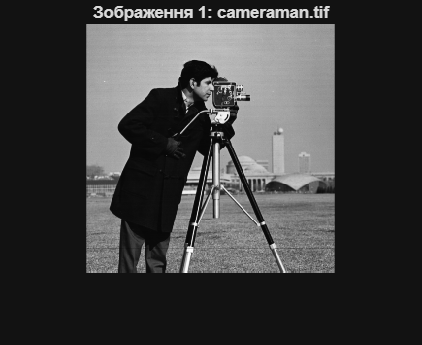

image1 = imread('cameraman.tif');
image2 = imread('peppers.png');
image3 = imread('moon.tif');

% Відображення зображень
figure, imshow(image1), title('Зображення 1: cameraman.tif');

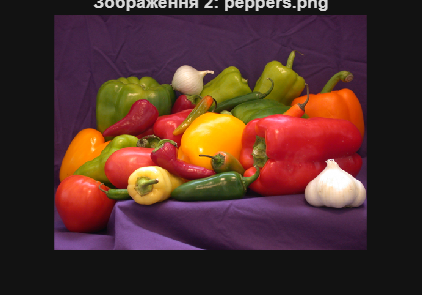

figure, imshow(image2), title('Зображення 2: peppers.png');

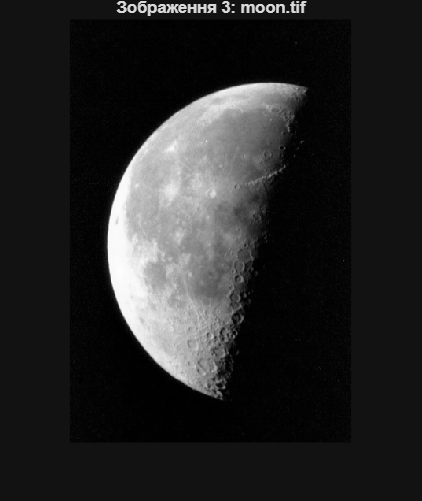

figure, imshow(image3), title('Зображення 3: moon.tif');

## 2. З використанням функції F = fft2(f) сформуйте й відобразіть двовимірні спектри зображень.

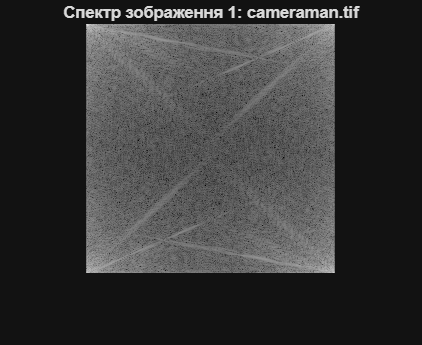

F1 = fft2(image1);
image2_gray = rgb2gray(image2); 
F2 = fft2(image2_gray);
F3 = fft2(image3);

% Нормалізація спектрів для відображення
F1_log = log(abs(F1) + 1);
F2_log = log(abs(F2) + 1);
F3_log = log(abs(F3) + 1);

% Відображення спектрів
figure, imshow(F1_log, []), title('Спектр зображення 1: cameraman.tif');

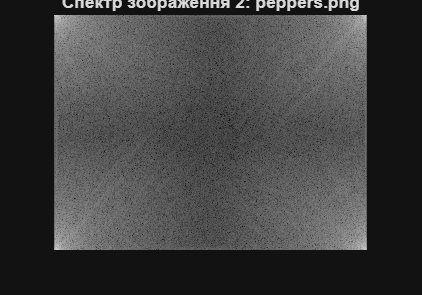

figure, imshow(F2_log, []), title('Спектр зображення 2: peppers.png');

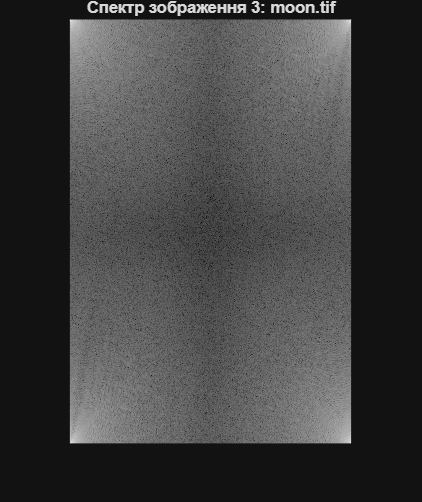

figure, imshow(F3_log, []), title('Спектр зображення 3: moon.tif');

## 3. З використанням функції fftshift приведіть нульову частоту в спектрі до центру вікна відображення.

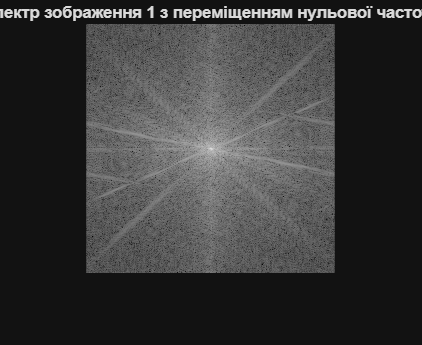

F1_shifted = fftshift(F1);
F2_shifted = fftshift(F2);
F3_shifted = fftshift(F3);

% Логарифмічне відображення спектрів
F1_shifted_log = log(abs(F1_shifted) + 1);
F2_shifted_log = log(abs(F2_shifted) + 1);
F3_shifted_log = log(abs(F3_shifted) + 1);

% Відображення спектрів з нульовою частотою в центрі
figure, imshow(F1_shifted_log, []), title('Спектр зображення 1 з переміщенням нульової частоти');

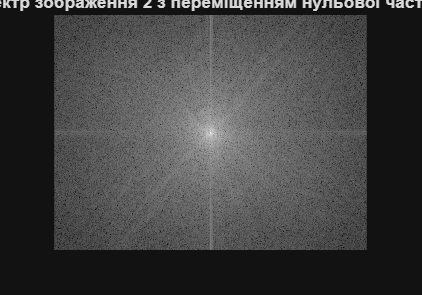

figure, imshow(F2_shifted_log, []), title('Спектр зображення 2 з переміщенням нульової частоти');

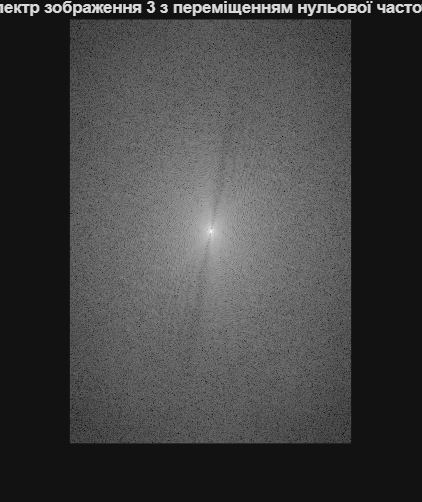

figure, imshow(F3_shifted_log, []), title('Спектр зображення 3 з переміщенням нульової частоти');

## 4. З використанням функції ifft2(F) відновіть зображення за його cпектром.

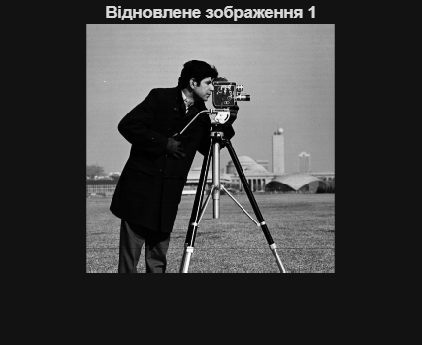

image1_recovered = ifft2(F1);
image2_recovered = ifft2(F2);
image3_recovered = ifft2(F3);

% Відображення відновлених зображень
figure, imshow(abs(image1_recovered), []), title('Відновлене зображення 1');

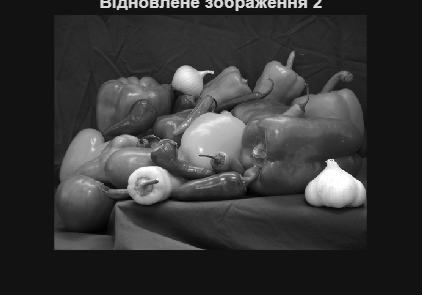

figure, imshow(abs(image2_recovered), []), title('Відновлене зображення 2');

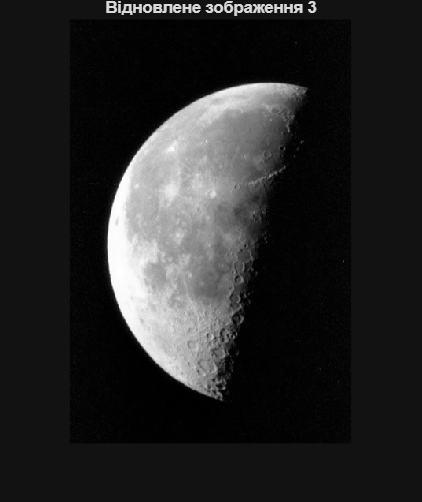

figure, imshow(abs(image3_recovered), []), title('Відновлене зображення 3');

## 5. З використанням функції fspecial('gaussian') задайте двовимірний фільтр із параметрами [M N], sigma в області просторових змінних.

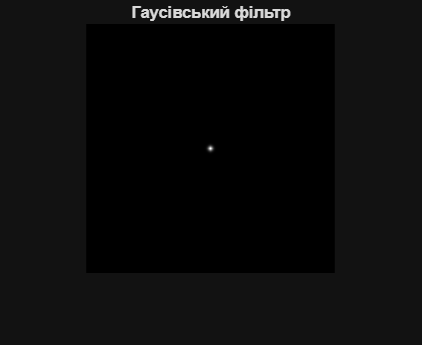

[M, N] = size(image1); % Розміри зображення
sigma = 2; % Параметр для гаусівського фільтра

% Створення двовимірного гаусівського фільтра
h = fspecial('gaussian', [M N], sigma);

% Відображення фільтра
figure, imshow(h, []), title('Гаусівський фільтр');

## 6. Визначте вигляд частотної характеристики даного фільтра.

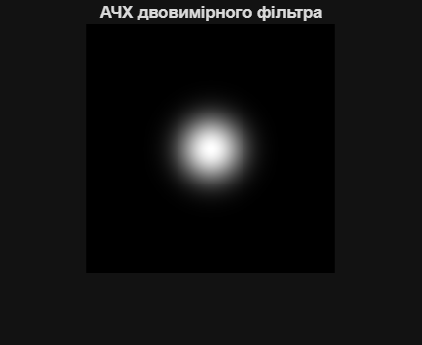

H = fft2(h);

% Переміщення нульової частоти в центр
H_shifted = fftshift(H);

% Нормалізація та логарифмічне відображення АЧХ
H_shifted_log = log(abs(H_shifted) + 1);

% Відображення АЧХ фільтра
figure, imshow(H_shifted_log, []), title('АЧХ двовимірного фільтра');

## 7. Змініть параметр sigma фільтра, і повторіть п.п. 5,6. Поясніть відмінності в отриманих результатах.

function [h_new,H_new_shifted,H_new_shifted_log] = fun(image,sigma_)
    h_new = fspecial('gaussian', size(image), sigma_);
    H_new = fft2(h_new);
    H_new_shifted = fftshift(H_new);
    H_new_shifted_log = log(abs(H_new_shifted) + 1);

end
sigma_new = 5; % Новий параметр sigma

[h_new, H_new_shifted, H_new_shifted_log] = fun(image1,sigma_new)

h_new =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

H_new_shifted =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.0000 - 0.

H_new_shifted_log =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     

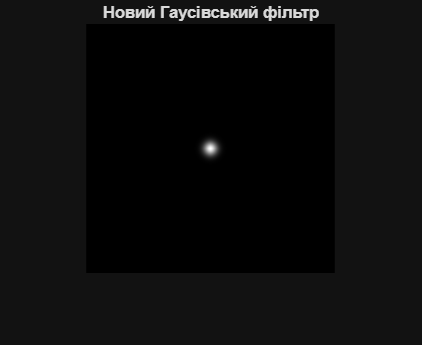

% Відображення нового фільтра та його АЧХ
figure, imshow(h_new, []), title('Новий Гаусівський фільтр');

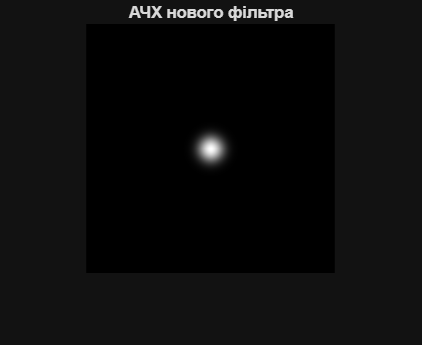

figure, imshow(H_new_shifted_log, []), title('АЧХ нового фільтра');

## 8. Виконайте фільтрацію зображень у частотній області з використанням фільтрів згідно п.п. 5, 6, 7.

% Перетворення зображень у частотну область
F1_shifted = fftshift(fft2(image1));
F2_shifted = fftshift(fft2(image2_gray));
F3_shifted = fftshift(fft2(image3));

% Фільтрація зображень за допомогою фільтра
F1_filtered = F1_shifted .* H_new_shifted;
[h_new_image2, H_new_shifted_image2, H_new_shifted_log_image2] = fun(image2_gray, sigma_new)

h_new_image2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0    

H_new_shifted_image2 =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.00

H_new_shifted_log_image2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0    

F2_filtered = F2_shifted .* H_new_shifted_image2;
[h_new_image3, H_new_shifted_image3, H_new_shifted_log_image3] = fun(image3, sigma_new)

h_new_image3 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0    

H_new_shifted_image3 =    0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i
   0.0000 + 0.0000i  -0.00

H_new_shifted_log_image3 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0    

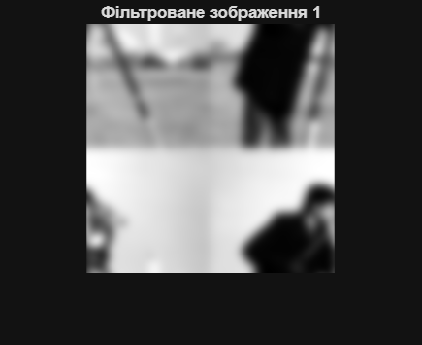

F3_filtered = F3_shifted .* H_new_shifted_image3;

% Перетворення назад у просторову область
image1_filtered = ifft2(ifftshift(F1_filtered));
image2_filtered = ifft2(ifftshift(F2_filtered));
image3_filtered = ifft2(ifftshift(F3_filtered));

% Відображення фільтрованих зображень
figure, imshow(abs(image1_filtered), []), title('Фільтроване зображення 1');

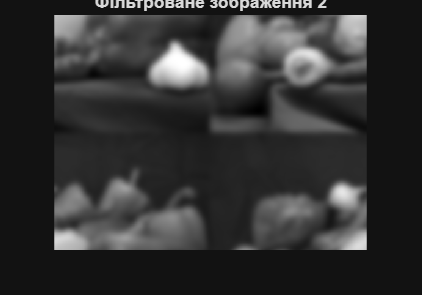

figure, imshow(abs(image2_filtered), []), title('Фільтроване зображення 2');

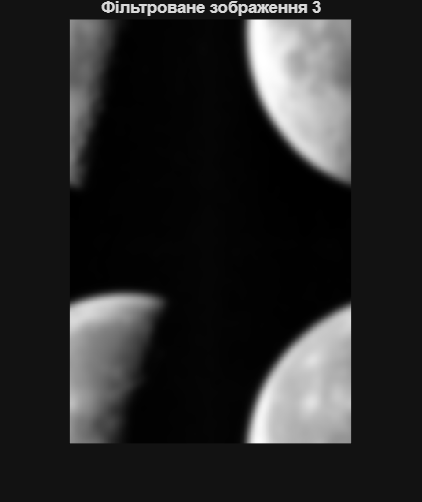

figure, imshow(abs(image3_filtered), []), title('Фільтроване зображення 3');

## 9. З використанням того самого віконного фільтра, заданого функцією fspecial('gaussian'), виконайте фільтрацію зображення в області просторових змінних.

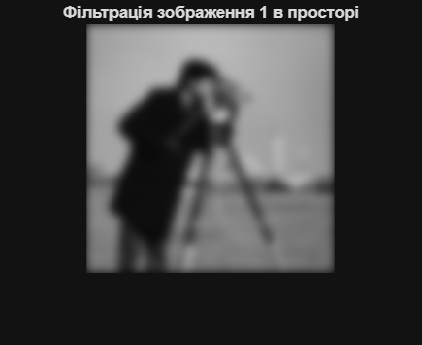

image1_spatial_filtered = imfilter(image1, h_new);
image2_spatial_filtered = imfilter(image2, h_new_image2);
image3_spatial_filtered = imfilter(image3, h_new_image3);

% Відображення результатів фільтрації в просторовій області
figure, imshow(image1_spatial_filtered), title('Фільтрація зображення 1 в просторі');

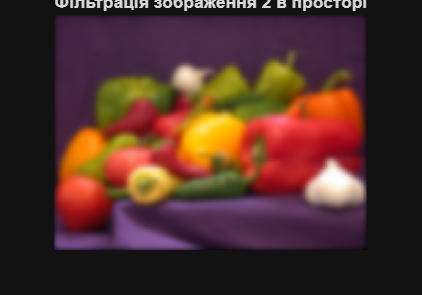

figure, imshow(image2_spatial_filtered), title('Фільтрація зображення 2 в просторі');

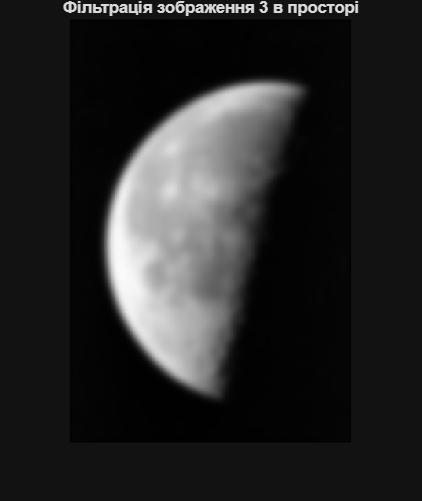

figure, imshow(image3_spatial_filtered), title('Фільтрація зображення 3 в просторі');